434 HW 2 Isaac Shelby 

1) There is only one way to roll a 2 with two die: both are ones. There are six ways to roll a 7: 1 and 6, 2 and 5, 3 and 4 (two ways for each of these with the two die). As each die has 6 possible outcomes, there are 36 total outcomes for rolling the 2 dice. Thus, the probability of rolling a 2 when rolling 2 six-sided dice is 1/36, whereas the probability of rolling a 7 is 6/36 or 1/6. The probability of rolling a 7 is 6 times as likely as rolling a 2.

2) We have already begun the process of determining the pdf for the sum of rolling two die and we can continue to do so below. Following the method of convolution, we can think of sliding the two numberlines 1-6 and 6-1 past each other. Starting with just 1 and 1 overlapping, and continuing by one jump at a time, we can see that the sum of all pairs remains fixed. Similarly, by sliding them past each other by one space, the sum only increases or decreases by one. This starting with 1/36 probability (1/6*1/6) for a sum of 2, the probability increases by 1/36 up to a maximum of 6/36 (for a sum of 7) when the numberlines completely overlap. Then they decrease by 1/36 at a time.

P(2) = 1/36, P(3) = 2/36, P(4) = 3/36, P(5) = 4/36, P(6) = 5/36, P(7) = 6/36, P(8) = 5/36, P(9) = 4/36, P(10) = 3/36, P(11) = 2/36, P(12) = 1/36.  

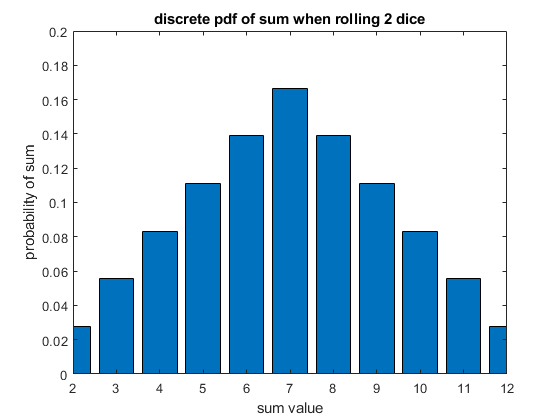

die_min = 1;
die_max = 6;

die_vals = die_min:die_max;
die_probs = unidpdf(die_vals, die_max);

sum_min = 2*die_min;
sum_max = 2*die_max;
sum_vals = sum_min:sum_max;
prob_of_sum = conv(die_probs, die_probs);

figure(1)
bar(sum_vals,prob_of_sum)
title('discrete pdf of sum when rolling 2 dice')
ylabel('probability of sum')
xlabel('sum value')
ylim([0,0.2]);
xlim([2,12])

3) Mean of a discrete variable $X$ with proability function $P(X)$ is defined as the sum over all possible values of $X$, $\{x_i \}$  weighted by their respective probabilities: $\mathbb{E}(X) = \sum_{x_i} x_i \times P(X = x_i)$. 

mean_of_sum_of_two_die = dot(prob_of_sum, sum_vals)

mean_of_sum_of_two_die = 7

The variance of a discrete variable $X$ is defined as the difference in the mean of the variable squared minus the square of the mean of the variable: $\text{Var}(X) = \mathbb{E}(X^2) - \mathbb{E}(X)^2 = \sum_{x_i} x_i ^2 \times P(X = x_i) - \left(\sum_{x_i} x_i \times P(X = x_i) \right)^2$

expectation_of_sum_squared = dot(prob_of_sum, sum_vals.^2);
variance_of_sum_of_two_die = expectation_of_sum_squared - mean_of_sum_of_two_die^2

variance_of_sum_of_two_die = 5.8333

4) The pdf for the average of 10 dice is *nearly* identical to the pdf for the sum of 10 dice. The probability distribution has the same shape, but by dividing out the values by 10 to obtain the average, it shrinks the width of the distribution:

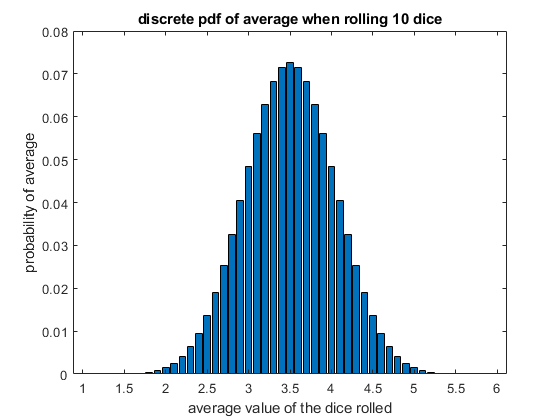

number_of_dice = 10;

for i = 1:number_of_dice
    if i == 1
        pdf_of_sum = die_probs;
    else
        temp = conv(pdf_of_sum, die_probs);
        pdf_of_sum = temp;
    end
end

n_sum_min = number_of_dice*die_min;
n_sum_max = number_of_dice*die_max;

n_sum_vals = n_sum_min:n_sum_max;
n_avg_vals = n_sum_vals / number_of_dice;

figure(2)
bar(n_avg_vals, pdf_of_sum)

title(['discrete pdf of average when rolling ' num2str(number_of_dice)  ' dice'])
ylabel('probability of average')
xlabel('average value of the dice rolled')

This looks very much like a Gaussian distribution. The central limit theorem states that taking the average of $n$ random samples pulled from identical distributions with the same mean and finite variance, the limiting form of the distribution is the standard normal distribution (https://en.wikipedia.org/wiki/Central_limit_theorem). So, in one way it is like the normal distribution. But, this is still a discrete distribution, we haven't yet taken the number of dice that we are averaging together towards infinity. And in a real experiment, with a finite number of measurements, the distribution will always remain discrete. So while the discrete values of the distribution will approach values equivalent to evaluating a normal distribution at those points, it will still be a discrete distribution. Below, we plot the discrete distribution and limiting distribution on the same axes. The limitng distribution has mean of 3.5 and variance of $2.9167 / n$. (The 2.9167 comes from the variance of a single die, calculated below as well). Note that we carefull choose to bin the analytic normal distribution we are plotting with the same number of bins as the discrete distribution has. We see good agreement in the center of the distribution, with increasing error towards the tails. 

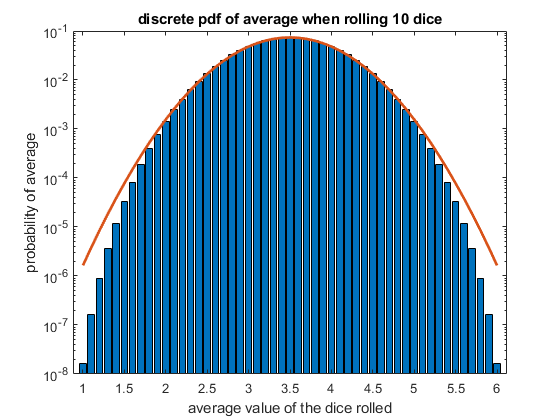

single_die_mean = dot(die_vals, die_probs);
single_die_variance = dot(die_vals.^2, die_probs) - dot(die_vals, die_probs)^2;

limiting_distribution = makedist("Normal","mu",single_die_mean,"sigma",sqrt(single_die_variance / number_of_dice));
x = linspace(1, 6, (die_max-1)*number_of_dice + 1 );
limiting_pdf = pdf(limiting_distribution,x);
limiting_pdf = limiting_pdf / sum(limiting_pdf);

figure(2)
bar(n_avg_vals, pdf_of_sum)
hold on

title(['discrete pdf of average when rolling ' num2str(number_of_dice)  ' dice'])
ylabel('log probability of average')
xlabel('average value of the dice rolled')
plot(x,limiting_pdf,"LineWidth",2);
set(gca,'YScale','log')

 5) 